# Covid classification - LSTM

remove previous data

close all; clc; clear;

Create audioDatastore objects of the data and split it into train, validation and test sets

dataset_name = "all"; % choose dataset
shuffle_dataset = "no"; % choose if to shuffle the datasets

% load data
[adsTrain, adsVal, adsTest] = load_datasets(shuffle_dataset, dataset_name);

extract auto-segmentation results from yamnet model

% pre-processing - cough event indices
[FeaturesTrain, trueLabelsTrain, adsSpecsTrain] = preprocess_classification_LSTM(adsTrain);

features extraction for segmentation done!!
segmentation done!!
features extraction for classification done!!


[FeaturesVal, trueLabelsVal, adsSpecsVal] = preprocess_classification_LSTM(adsVal);

features extraction for segmentation done!!
segmentation done!!
features extraction for classification done!!


Define the LSTM network architecture. Specify the input size as 12 (the number of features of the input data). Specify an LSTM layer to have 100 hidden units and to output the last element of the sequence. Finally, specify nine classes by including a fully connected layer of size 9, followed by a softmax layer and a classification layer.

inputSize = 12;
numHiddenUnits = 10;
numClasses = 2;

layers = [ ...
    sequenceInputLayer(inputSize)
    lstmLayer(numHiddenUnits, 'OutputMode', 'last')
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer];

Specify the training options. Specify the solver as `'adam'` and `'GradientThreshold'` as 1. Set the mini-batch size to 27 and set the maximum number of epochs to 70.

Because the mini-batches are small with short sequences, the CPU is better suited for training. Set `'ExecutionEnvironment'` to `'cpu'`. To train on a GPU, if available, set `'ExecutionEnvironment'` to `'auto'` (the default value).

miniBatchSize = 32;
MaxEpochs = 10;
InitialLearnRate = 0.001;
L2Regularization =0.01;
validationFrequency = floor(numel(trueLabelsTrain)/miniBatchSize);

% maxEpochs = 10;
% miniBatchSize = 10;
% 
% options = trainingOptions('adam', ...
%     'ExecutionEnvironment','auto', ...
%     'MaxEpochs', maxEpochs, ...
%     'MiniBatchSize', miniBatchSize, ...
%     'GradientThreshold', 1, ...
%     'Verbose', true, ...
%     'Plots','training-progress', ...
%     'ValidationData', {FeaturesVal, trueLabelsVal}, ...
%     'SequencePaddingDirection', 'left' ...
%     );

options = trainingOptions( ...
    'adam', ...
    'Plots', 'training-progress', ...
    'Verbose', true, ...
    'MaxEpochs', MaxEpochs, ...
    'MiniBatchSize', miniBatchSize, ...
    'Shuffle', 'every-epoch', ...
    'ValidationData', {FeaturesVal, trueLabelsVal}, ...
    'ValidationFrequency', validationFrequency, ...
    'InitialLearnRate', InitialLearnRate, ...
    'LearnRateSchedule', 'piecewise', ...
    'LearnRateDropPeriod', 1, ...
    'LearnRateDropFactor', 0.1, ...
    'L2Regularization', L2Regularization, ...
    'SequencePaddingDirection', 'left' ...
    );

Train the LSTM network with the specified training options.

Training on single GPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:05 |       40.62% |       45.03% |       0.7366 |          NaN |          0.0010 |
|       1 |          17 |       00:00:06 |       43.75% |       43.71% |          NaN |          NaN |          0.0010 |
|       2 |          34 |       00:00:06 |       50.00% |       43.71% |          NaN |          NaN |          0.0001 |
|       3 |          50 |       00:00:06 |       25.00% |              |          NaN |              |      1.0000e-05 |
|       

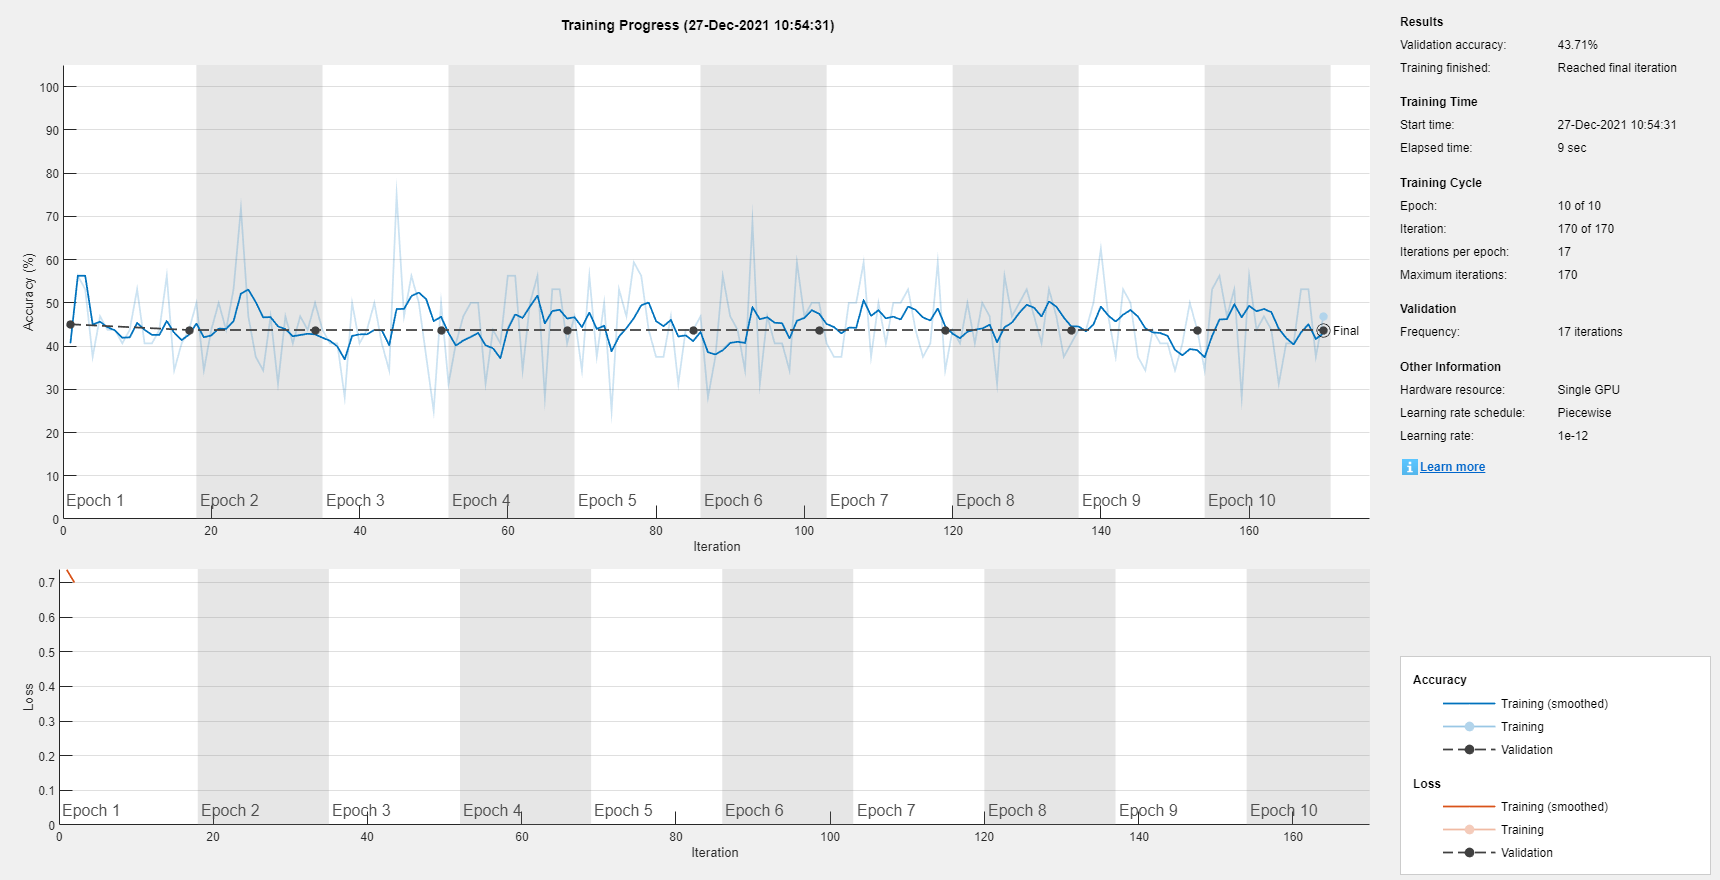

net_LSTM = trainNetwork(FeaturesTrain, trueLabelsTrain, layers, options);

% analyzeNetwork(net_LSTM);

Load the test set and classify the sequences into speakers.

[FeaturesTest, trueLabelsTest, adsSpecsTest] = preprocess_classification_LSTM(adsTest);

features extraction for segmentation done!!
segmentation done!!
features extraction for classification done!!


Classify the test data. Specify the same mini-batch size used for training.

predLabels = classify(net_LSTM, FeaturesTest, 'MiniBatchSize', miniBatchSize);

Calculate the classification accuracy of the predictions.

acc = sum(predLabels == trueLabelsTest)./numel(trueLabelsTest)

acc = 0